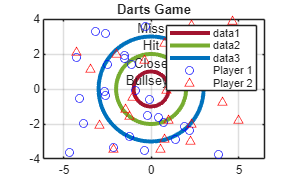

% S21 Darts
% Calculates and plots dart scores for two players
% Name: Nolan Hendrickson
% Section: L27
% Team: 3

clear; clc; close all

a = arduino();  % Automatically finds the connected Arduino board

% Define LED pins (change these if your wiring is different)
player1LED = 'D3';  % Player 1 = blue LED on pin D3
player2LED = 'D4';  % Player 2 = red LED on pin D4
tieLED     = 'D5';  % Tie = yellow LED on pin D5

% Turn off all LEDs before deciding
writeDigitalPin(a, player1LED, 0);
writeDigitalPin(a, player2LED, 0);
writeDigitalPin(a, tieLED, 0);

% Define target radii
inner = 1; % radius for bullseye
middle = 2; % radius for close
outer = 3; % radius for hit
board_limit = 4; % beyond this is missed target entirely

% Plot the dartboard
dartplotinput(inner, middle, outer);
hold on;

% Load data from Excel
% Player1_X, Player1_Y,  Player2_X,  Player2_Y
[x1, y1, x2, y2] = readvars('darts_game.xlsx');

% Plot dart positions
plot(x1, y1, 'bo', 'DisplayName', 'Player 1');
plot(x2, y2, 'r^', 'DisplayName', 'Player 2');
legend show;
axis equal;
title('Darts Game');


% Calculate distances from origin
n = length(x1); % assume both players have same number of darts
d1 = zeros(1, n);
d2 = zeros(1, n);

for i = 1:n
    SLD1(i) = sqrt(x1(i)^2 + y1(i)^2);
    SLD2(i) = sqrt(x2(i)^2 + y2(i)^2);
end

% Scoring function
score1 = zeros(1, n);
score2 = zeros(1, n);

for i = 1:n
    % Player 1 scoring
    if abs(x1(i)) > board_limit || abs(y1(i)) > board_limit
        score1(i) = -1;
    elseif SLD1(i) < inner
        score1(i) = 4;
    elseif SLD1(i) < middle
        score1(i) = 2;
    elseif SLD1(i) < outer
        score1(i) = 1;
    else
        score1(i) = 0;
    end

    % Player 2 scoring
    if abs(x2(i)) > board_limit || abs(y2(i)) > board_limit
        score2(i) = -1;
    elseif SLD2(i) < inner
        score2(i) = 4;
    elseif SLD2(i) < middle
        score2(i) = 2;
    elseif SLD2(i) < outer
        score2(i) = 1;
    else
        score2(i) = 0;
    end
end

% Calculate total scores
total1 = sum(score1);
total2 = sum(score2);

% Determine winner 
if total1 > total2
    result = sprintf('Player 1 wins! Score: %d to %d', total1, total2);
elseif total2 > total1
    result = sprintf('Player 2 wins! Score: %d to %d', total2, total1);
else
    result = sprintf('It''s a tie! Both scored %d points.', total1);
end

disp(result)

Player 1 wins! Score: 14 to 6



% Light up the appropriate LED
if total1 > total2
    writeDigitalPin(a, player1LED, 1);
    disp('Lighting up Player 1 LED (Blue');
elseif total2 > total1
    writeDigitalPin(a, player2LED, 1);
    disp('Lighting up Player 2 LED (Red)');
else
    writeDigitalPin(a, tieLED, 1);
    disp('Lighting up Tie LED (Yellow)');
end

Lighting up Player 1 LED (Blue



pause(5); % Keep the light on for 5 seconds (optional)
writeDigitalPin(a, player1LED, 0);
writeDigitalPin(a, player2LED, 0);
writeDigitalPin(a, tieLED, 0);